# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Disjoining pressure
c1 = 0.0010;  
c2 = 0.0196;
% Droplet locations
p0_1 = 5;
p0_2 = 7.5;
p0_3 = 10;

**Target  U=U0**

aa=-5;
bb=5;
cc=.5;
a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));
U0 = c;
target = [a,b,U0];

## **2) **

**Solutions**

p0=5 

simultaneous

[tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol,OUTS]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,p0_1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          32.7823         
     1            4          31.6899         initial simplex
     2            6          24.1529         expand
     3            7          24.1529         reflect
     4            9          21.7115         expand
     5           11          13.3297         expand
     6           13           7.5002         expand
     7           15          2.78585         expand
     8           16          2.78585         reflect
     9           17          2.78585         reflect
    10           18          2.78585         reflect
    11           19          2.78585         reflect
    12           21          1.55914         reflect
    13           22          1.55914         reflect
    14           24          1.55914         contract inside
    15           26          1.19485         contract outside
    16           28         0.452351         expand
    17           30         0.

successive

[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition,OUTS_Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,p0_1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          32.7823         
     1            2          32.7823         initial simplex
     2            4           24.149         expand
     3            6          12.8621         expand
     4            8          4.62611         expand
     5           10          4.62602         reflect
     6           12          4.62602         contract inside
     7           15          4.62602         shrink
     8           17          4.62602         contract outside
     9           20          4.62602         shrink
    10           22          4.62602         contract inside
    11           24          4.62602         contract inside
    12           26          4.62602         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 24.5


[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining,OUTS_Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          4.62602         
     1            3          4.56697         initial simplex
     2            5          2.41179         expand
     3            7         0.844324         expand
     4            9         0.512883         reflect
     5           11         0.500416         reflect
     6           13         0.500416         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.427794 seconds.


p0=7.5 

simultaneouse

[~,~,~,~,H_2,~,conds_Sol_2,...
    ~,~,output_2,history_2,History_2,h_Sol_2,H_Sol_2,OUTS_2]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,p0_2,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          57.9827         
     1            4          57.3057         initial simplex
     2            6          53.7422         expand
     3            8          46.9025         expand
     4           10          42.0011         expand
     5           12          30.8994         expand
     6           14          19.3631         expand
     7           16          3.57597         expand
     8           17          3.57597         reflect
     9           19          3.57597         expand
    10           20          3.57597         reflect
    11           21          3.57597         reflect
    12           26          3.57597         shrink
    13           27          3.57597         reflect
    14           28          3.57597         reflect
    15           30          3.57597         reflect
    16           32          3.57597         contract inside
    17           34          3.57597     

successive

[~,~,~,~,H_2Possition,~,conds_Sol_2Possition,...
    ~,~,output_2Possition,history_2Possition,History_2Possition,h_Sol_2Possition,H_Sol_2Possition,OUTS_2Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,p0_2,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          57.9827         
     1            2          57.9827         initial simplex
     2            4          52.7249         expand
     3            6          37.1519         expand
     4            8          5.93547         expand
     5           10          5.04315         reflect
     6           12          5.04315         contract inside
     7           15          5.04315         shrink
     8           17          4.62611         reflect
     9           19          4.62611         contract inside
    10           22          4.62611         shrink
    11           24          4.62611         contract inside
    12           26          4.62611         contract inside
    13           28          4.62611         contract inside
    14           30          4.62611         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 


[~,~,~,~,H_2Disjoining,myObjective_2Disjoining,conds_Sol_2Disjoining,...
    ~,~,output_2Disjoining,history_2Disjoining,History_2Disjoining,h_Sol_2Disjoining,H_Sol_2Disjoining,OUTS_2Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_2Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          4.62611         
     1            3          4.56716         initial simplex
     2            5          3.34022         expand
     3            7          3.30883         reflect
     4            9          3.30883         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 3.910348 seconds.


p0=10 

simultaneous

[~,~,~,~,H_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1,OUTS_1]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,p0_3,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          60.5334         
     1            4          59.2056         initial simplex
     2            6          56.7857         expand
     3            7          56.7857         reflect
     4            9          52.3076         expand
     5           11          46.3499         expand
     6           13          38.6985         expand
     7           15          3.57597         expand
     8           17          3.57597         reflect
     9           18          3.57597         reflect
    10           19          3.57597         reflect
    11           20          3.57597         reflect
    12           22          3.57597         contract inside
    13           24          3.57597         contract inside
    14           26          3.57597         contract inside
    15           28          3.57597         reflect
    16           33          3.57597         shrink
    17           34    

successive

[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition,OUTS_1Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,p0_3,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          60.5334         
     1            2          60.5334         initial simplex
     2            4          60.5334         reflect
     3            7          60.5334         shrink
     4            9          60.1267         reflect
     5           12          60.1267         shrink
     6           14          60.1267         contract outside
     7           16          60.1267         contract inside
     8           18          60.1267         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 17.047565 seconds.



[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining,OUTS_1Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_1Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          60.1267         
     1            3           59.591         initial simplex
     2            5          55.7134         expand
     3            7          51.3943         expand
     4            9          39.1532         expand
     5           11          18.1063         expand
     6           13          3.57597         expand
     7           14          3.57597         reflect
     8           16          3.57597         expand
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 6.290644 seconds.


Rearrganging things

nDisjoin = size(history_Disjoining);
nDisjoin = nDisjoin(1);
nPossition = size(history_Possition);
nPossition = nPossition(1); 
history1 = ones(nDisjoin+nPossition,3);
history1(1:nPossition,2:3) = [c1 c2].*ones(size(history_Possition));
history1(nPossition+1:end,2:3) = history_Disjoining;
history1(1:nPossition,1) = history_Possition;
history1(nPossition+1:end,1) = history_Possition(end).*ones(size(History_Disjoining));
History1 = [History_Possition;History_Disjoining];


nDisjoin_1 = size(history_1Disjoining);
nDisjoin_1 = nDisjoin_1(1);
nPossition_1 = size(history_1Possition);
nPossition_1 = nPossition_1(1); 
history1_1 = ones(nDisjoin_1+nPossition_1,3);
history1_1(1:nPossition_1,2:3) = [c1 c2].*ones(size(history_1Possition));
history1_1(nPossition_1+1:end,2:3) = history_1Disjoining;
history1_1(1:nPossition_1,1) = history_1Possition;
history1_1(nPossition_1+1:end,1) = history_1Possition(end).*ones(size(History_1Disjoining));
History1_1 = [History_1Possition;History_1Disjoining];


nDisjoin_2 = size(history_2Disjoining);
nDisjoin_2 = nDisjoin_2(1);
nPossition_2 = size(history_2Possition);
nPossition_2 = nPossition_2(1); 
history1_2 = ones(nDisjoin_2+nPossition_2,3);
history1_2(1:nPossition_2,2:3) = [c1 c2].*ones(size(history_2Possition));
history1_2(nPossition_2+1:end,2:3) = history_2Disjoining;
history1_2(1:nPossition_2,1) = history_2Possition;
history1_2(nPossition_2+1:end,1) = history_2Possition(end).*ones(size(History_2Disjoining));
History1_2 = [History_2Possition;History_2Disjoining];

**Figures**

p=5

successive

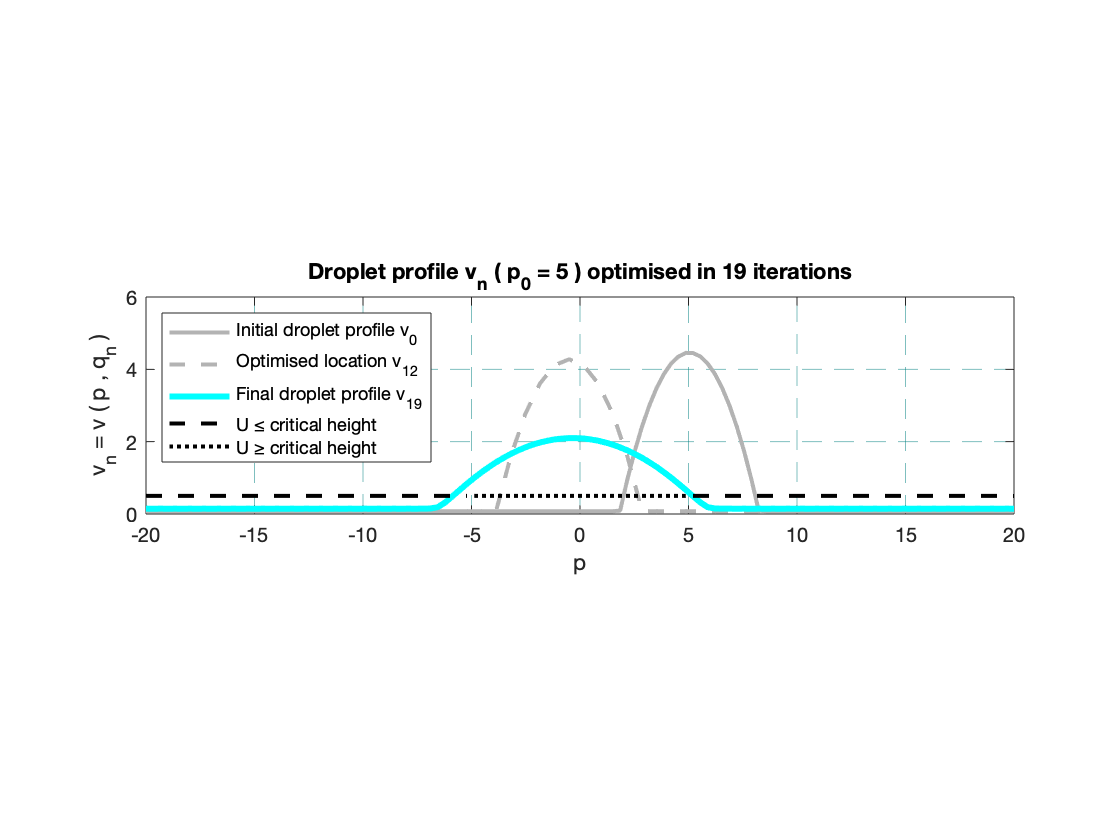

figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H0_Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_Disjoining,'c-','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised location v_{12}',...
    'Final droplet profile v_{19}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 5 ) optimised in 19 iterations');
hold off


OUTS

OUTS = 1×27 struct array with fields:
    iteration
    funccount
    fval
    procedure


simultaneous

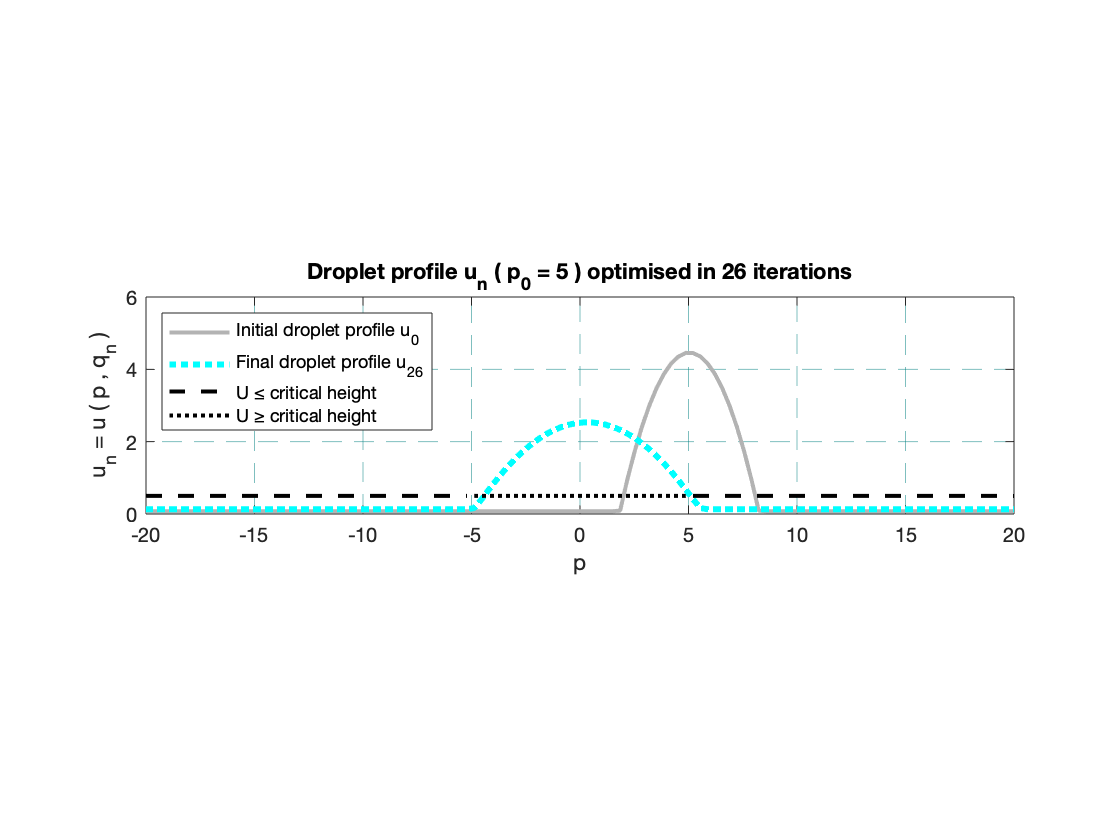

figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'c:','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{26}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 5 ) optimised in 26 iterations');
hold off

p=7.5

successive

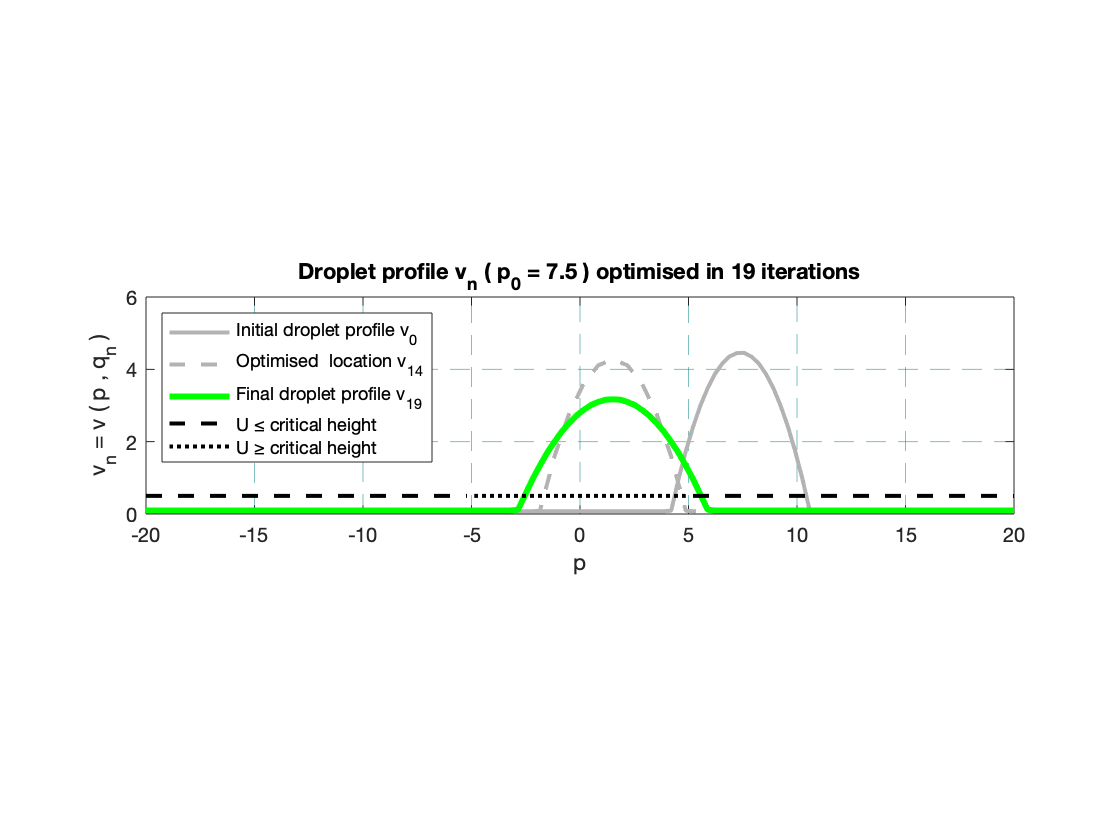

figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_2Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2Disjoining,'g-','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{14}',...
    'Final droplet profile v_{19}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title(['Droplet profile v_n ( p_0 = 7.5 ) optimised in 19 iterations']);
hold off

simultaneous

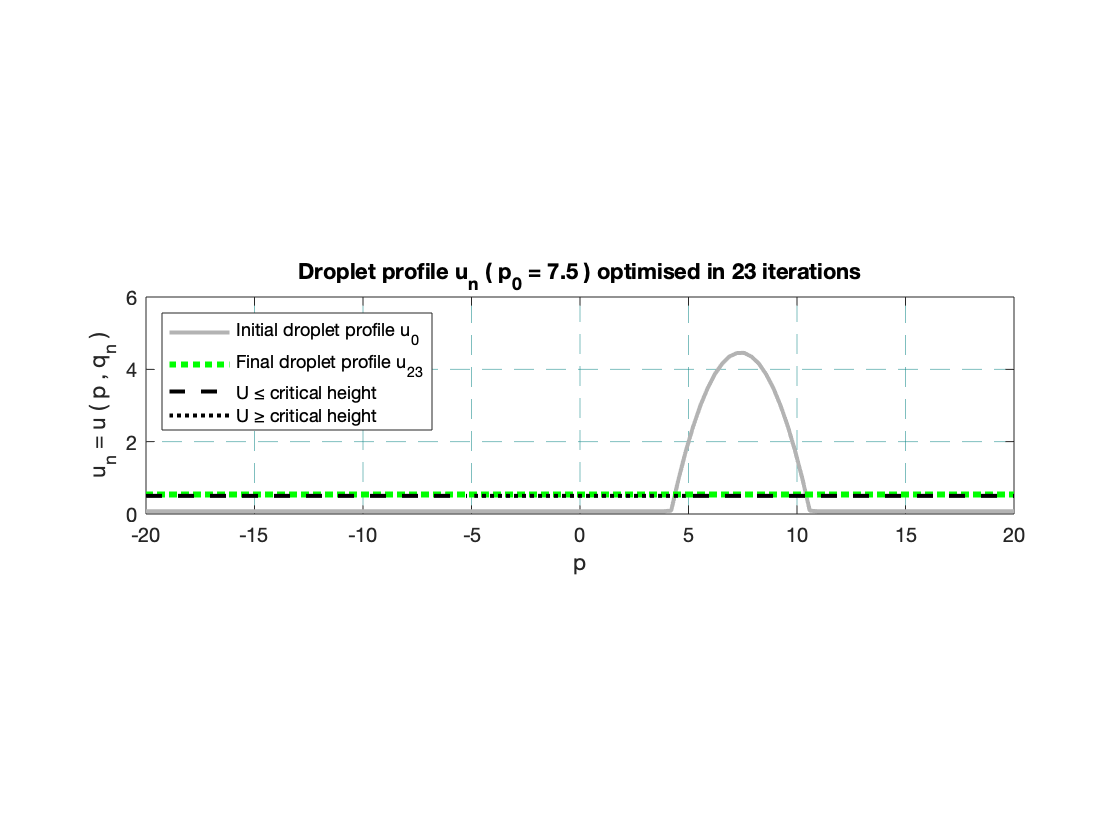

figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2,'g:','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{23}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 7.5 ) optimised in 23 iterations');
hold off

p=10

successive

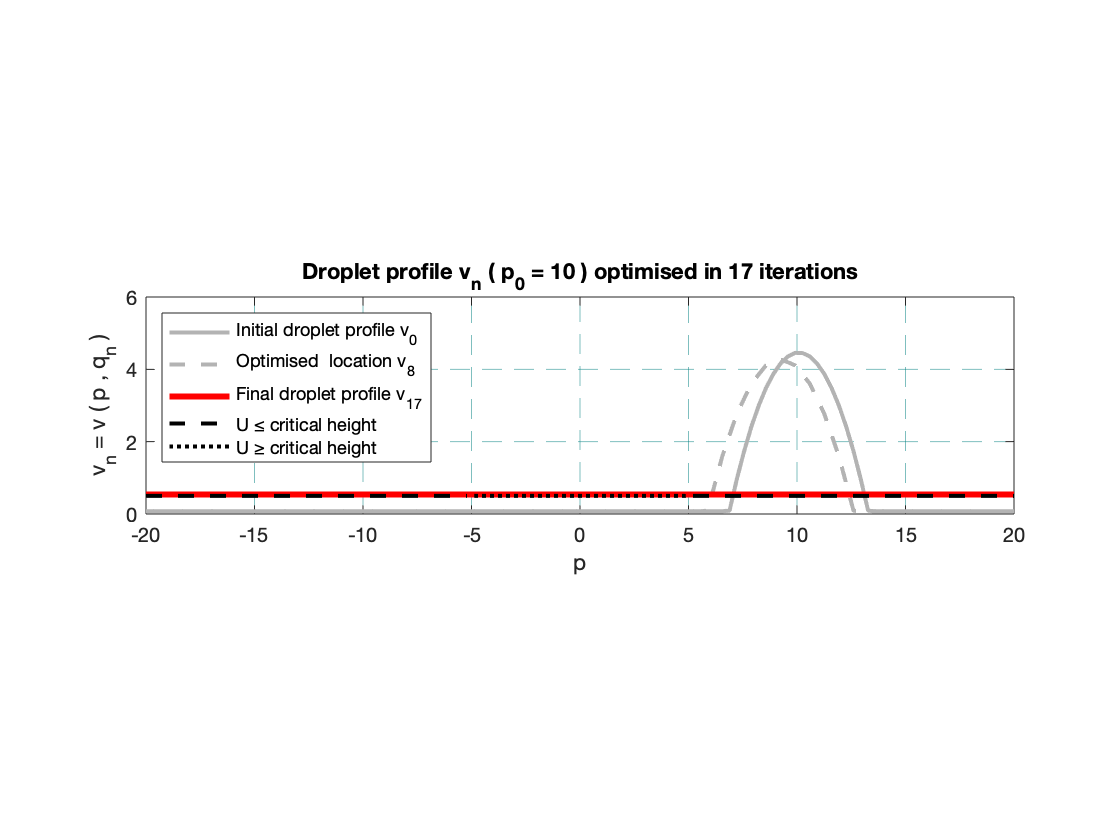

figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_1Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1Disjoining,'r-','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{8}',...
    'Final droplet profile v_{17}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 10 ) optimised in 17 iterations');
hold off

simultaneous

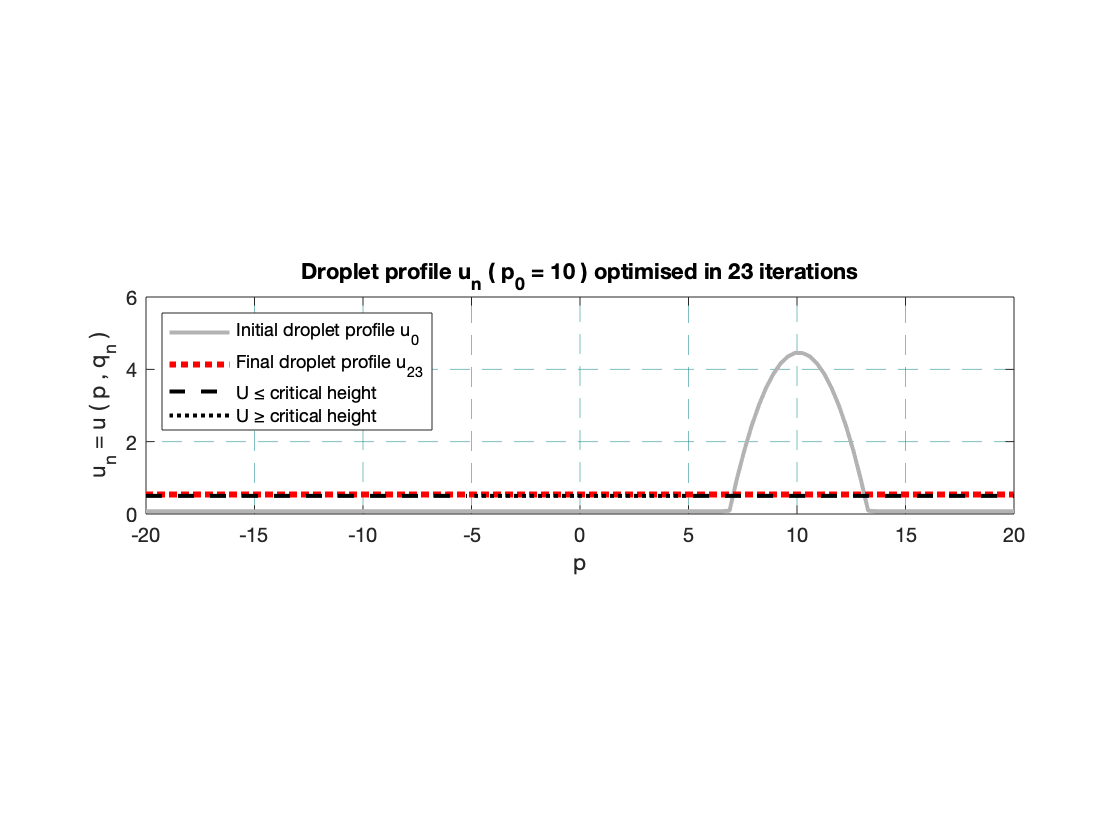

figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r:','linewidth',3);
plot(X(1:a),U0(1:a),'k--','linewidth',2);
plot(X(a+1:b),U0(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),U0(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{23}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 10 ) optimised in 23 iterations');
hold off

**Figurs for successive**

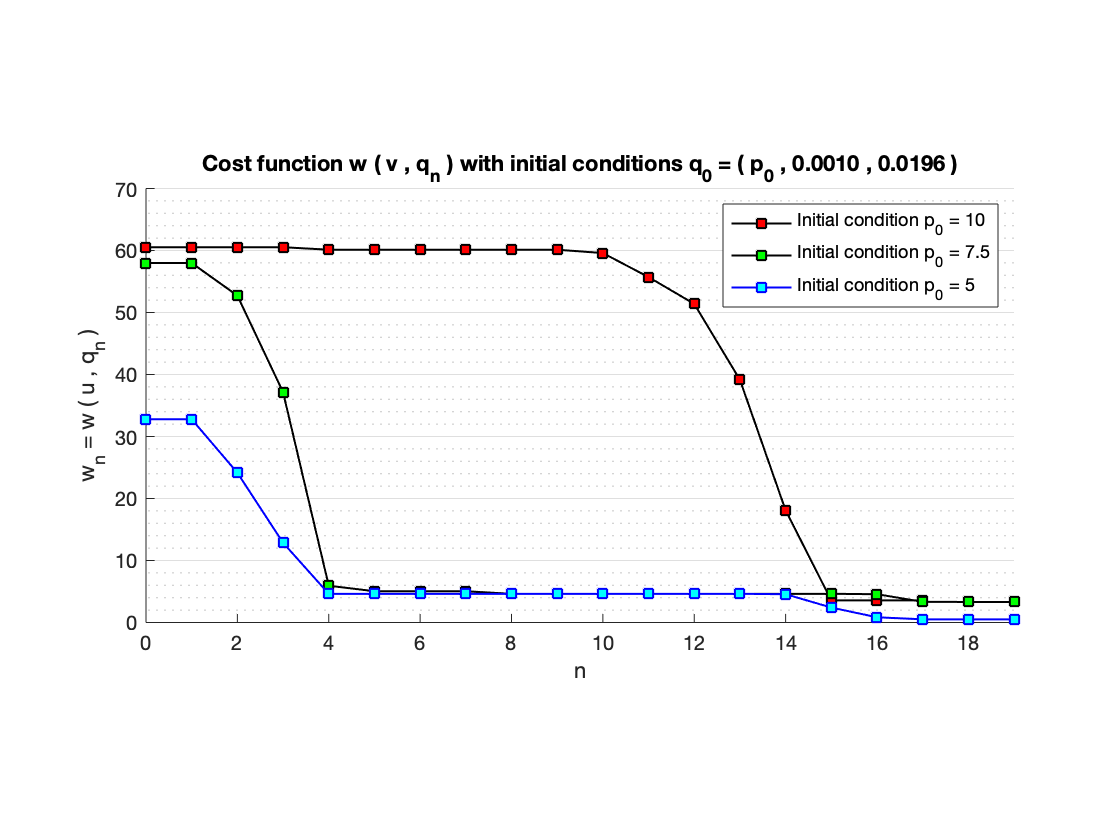

figure;
hold on
plot(0:17,History1_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,History1_2,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:19,History1,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Cost function w ( v , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 19]);
ylim([0 70]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',0:10:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

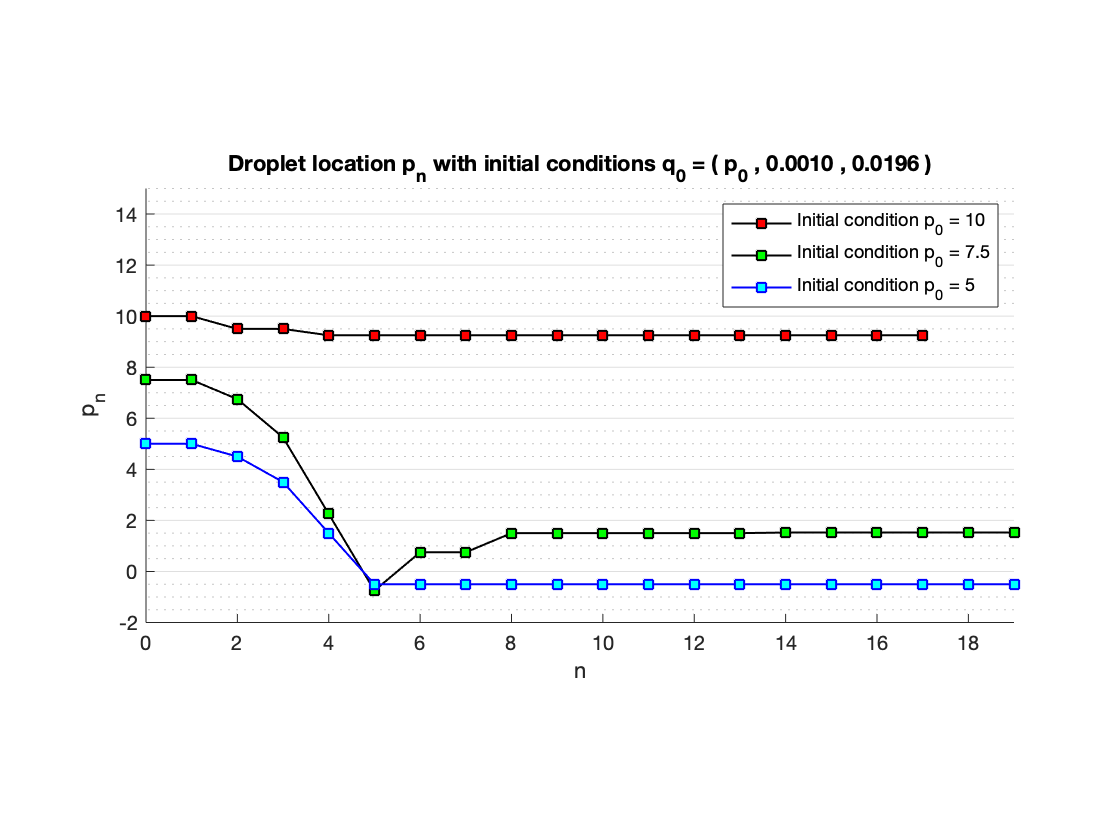


figure;
hold on
plot(0:17,history1_1(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history1_2(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:19,history1(:,1),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 19]);
ylim([-2 15]);
set(gca,'ytick',-2:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

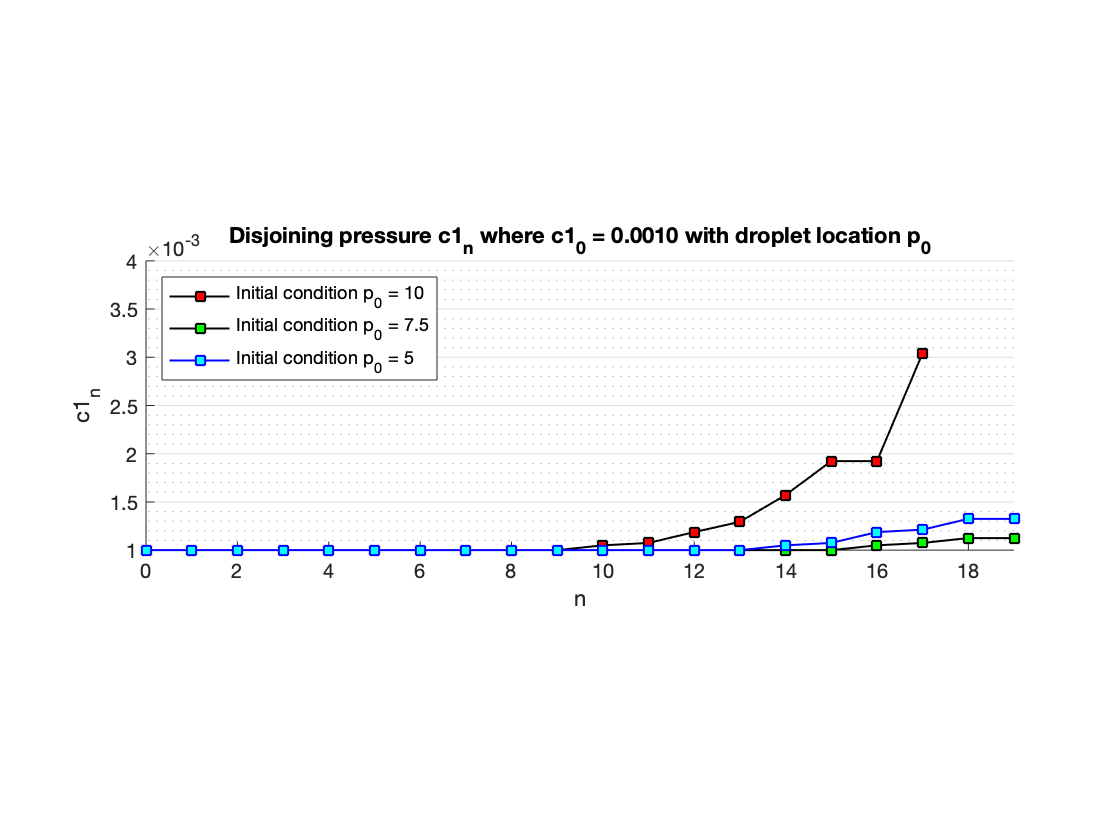


figure;
hold on
plot(0:17,history1_1(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history1_2(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:19,history1(:,2),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with droplet location p_0');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northwest');
xlim([0 19]);
ylim([.001 .004]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

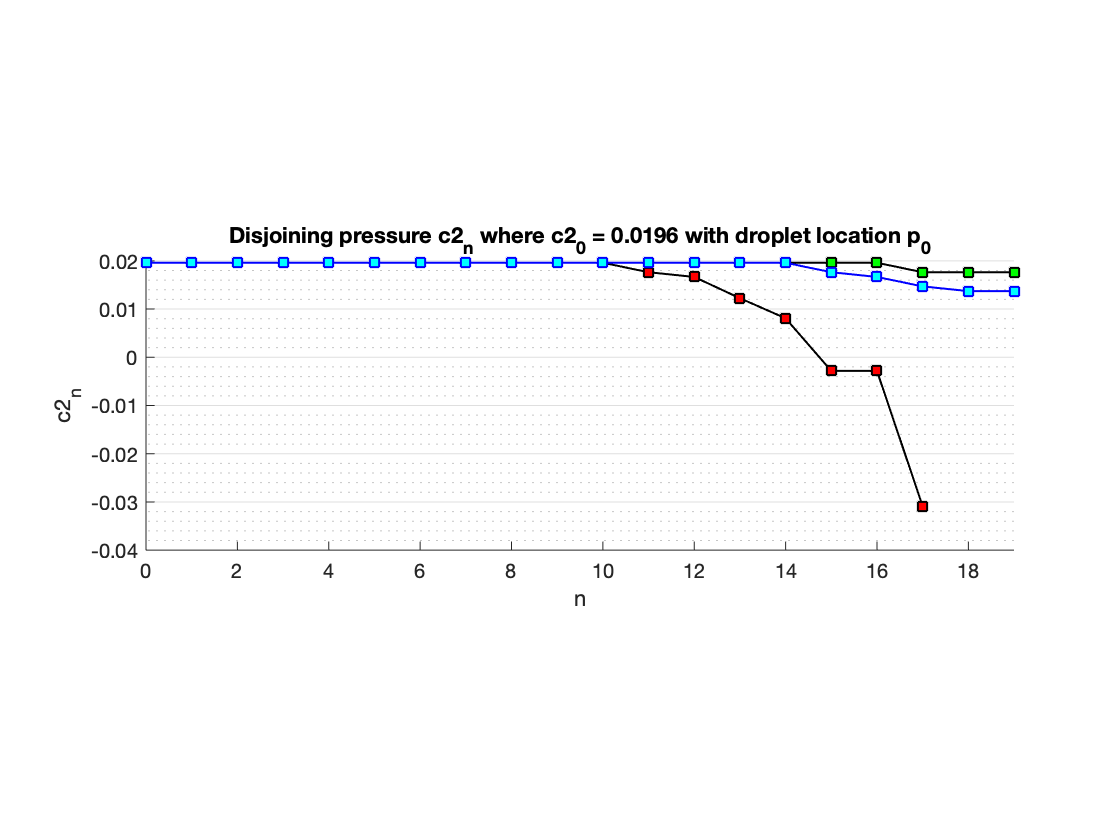


figure;
hold on
plot(0:17,history1_1(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history1_2(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:19,history1(:,3),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with droplet location p_0');
xlim([0 19]);
ylim([-.04 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

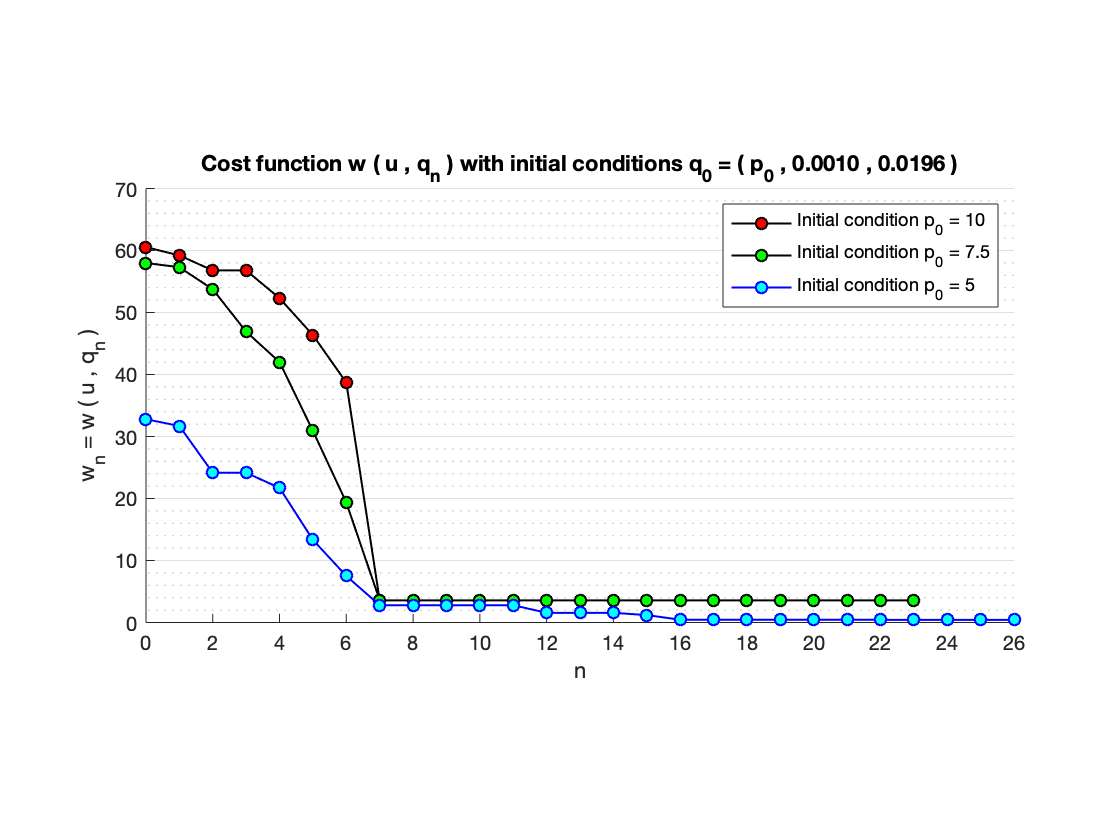

figure;
hold on
plot(0:23,History_1,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:23,History_2,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,History,'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Cost function w ( u , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 26]);
ylim([0 70]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',0:10:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

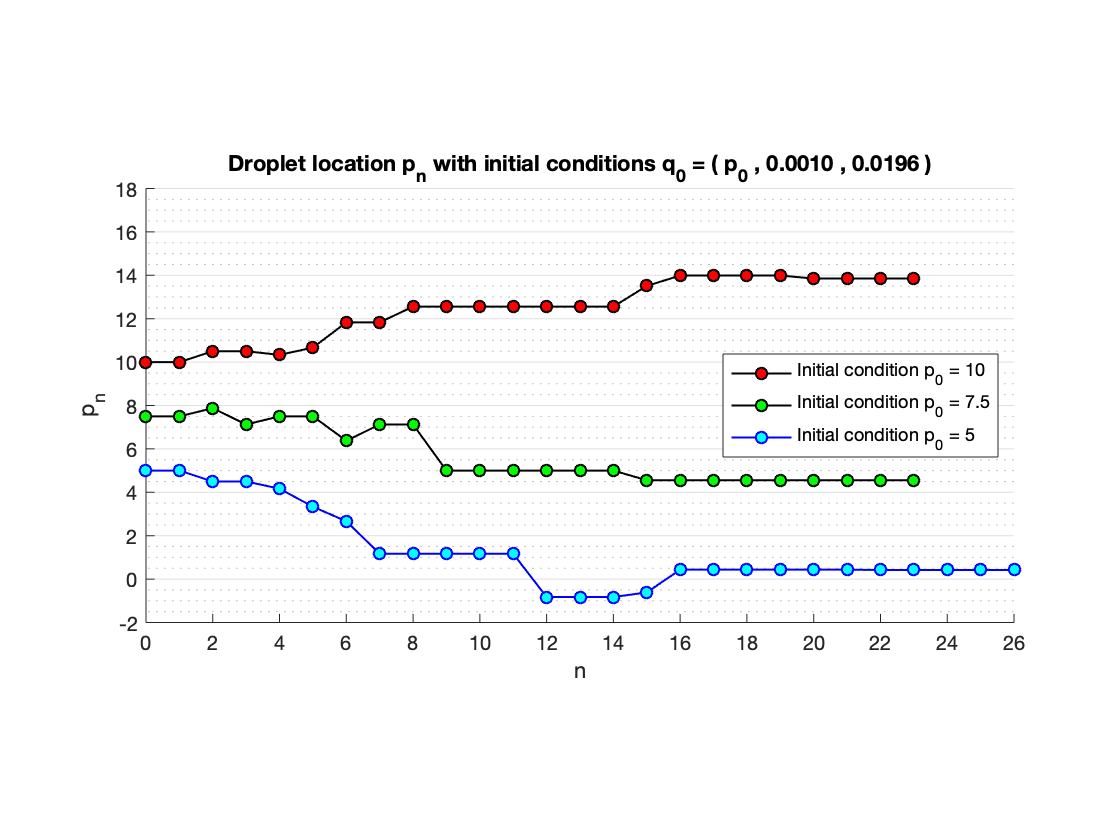


figure;
hold on
plot(0:23,history_1(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:23,history_2(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history(1,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
set(gca,'xtick',0:2:100);
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','east');
xlim([0 26]);
ylim([-2 18]);
set(gca,'ytick',-4:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

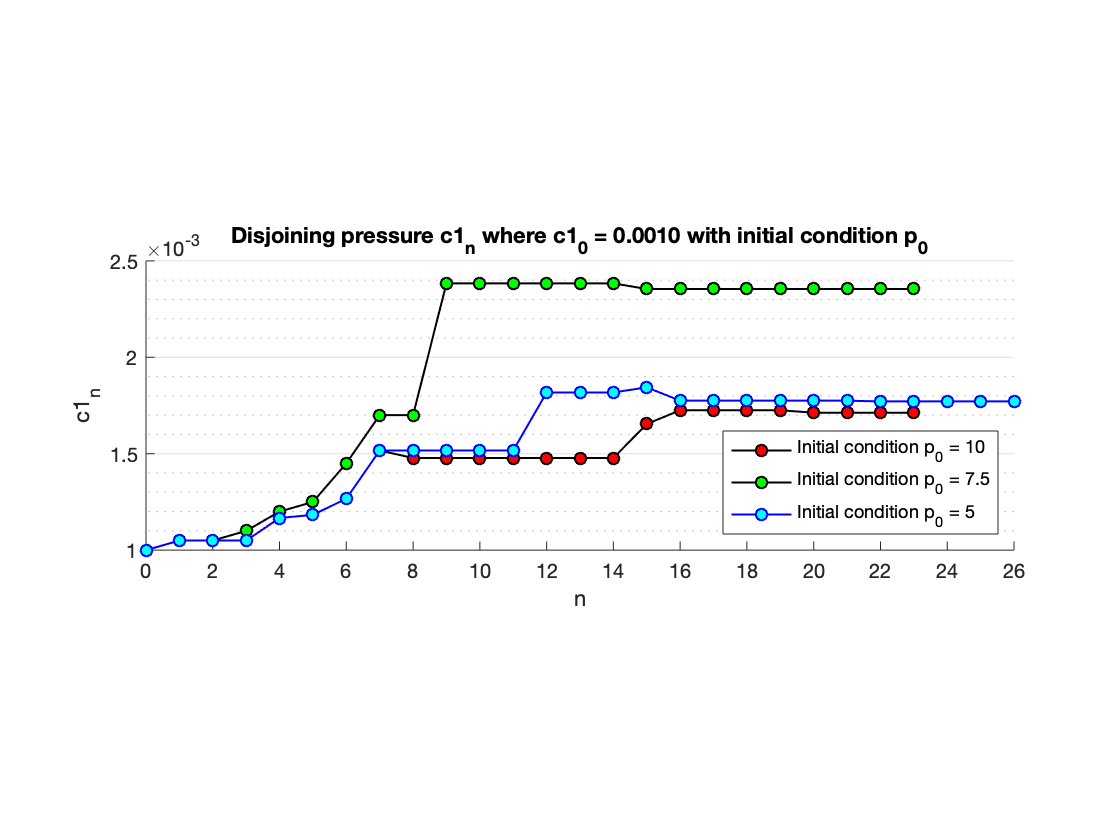


figure;
hold on
plot(0:23,history_1(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:23,history_2(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history(2,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
set(gca,'xtick',0:2:100);
title('Disjoining pressure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('Initial condition p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','southeast');
xlim([0 26]);
ylim([.001 .0025]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

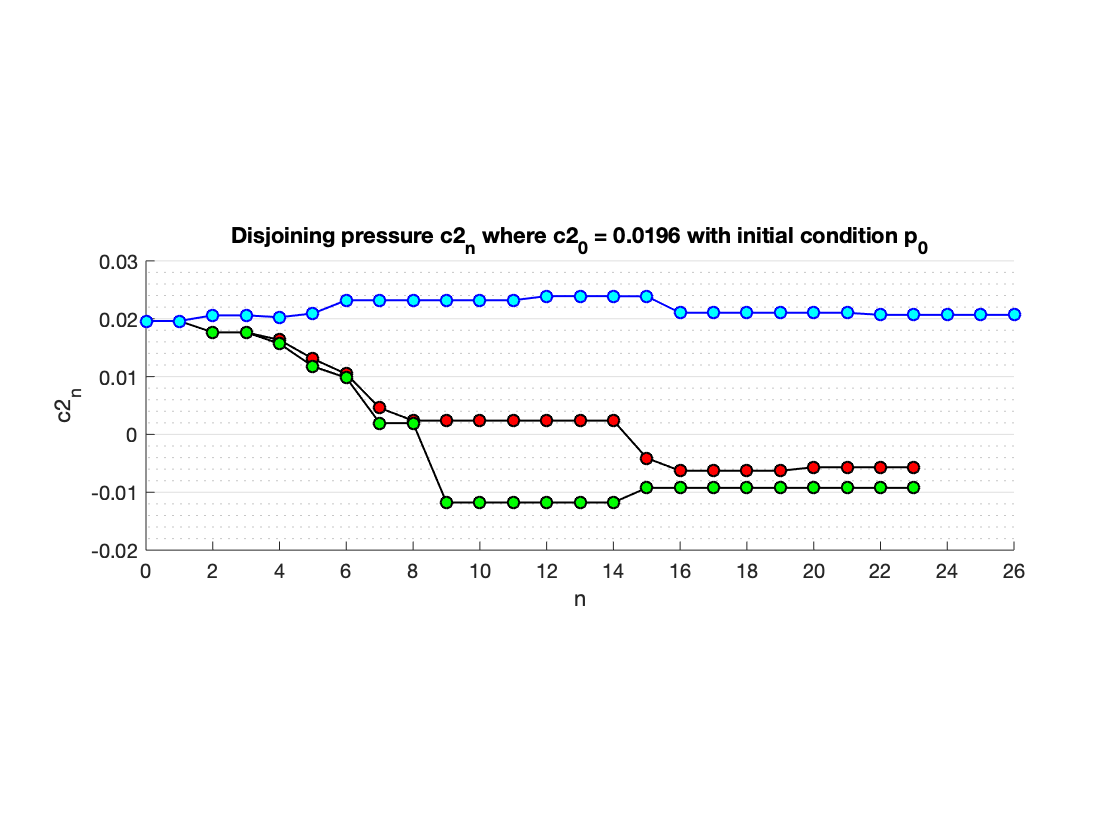


figure;
hold on
plot(0:23,history_1(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:23,history_2(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history(3,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
set(gca,'xtick',0:2:100);
title('Disjoining pressure c2_n where c2_0 = 0.0196 with initial condition p_0');
xlim([0 26]);
ylim([-.02 .03]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off